## Part 3 : Processing sound waves using Fourier Transform

Reading piano notes from Data/Piano/*.mp3 :

[y1,Fs1] = audioread('Data/Piano/piano_A.mp3');
[y2,Fs2] = audioread('Data/Piano/piano_A_sharp.mp3');
[y3,Fs3] = audioread('Data/Piano/piano_B.mp3');
[y4,Fs4] = audioread('Data/Piano/piano_C_sharp.mp3');
[y5,Fs5] = audioread('Data/Piano/piano_D.mp3');
[y6,Fs6] = audioread('Data/Piano/piano_D_sharp.mp3');
[y7,Fs7] = audioread('Data/Piano/piano_E.mp3');
[y8,Fs8] = audioread('Data/Piano/piano_F.mp3');
[y9,Fs9] = audioread('Data/Piano/piano_F_sharp.mp3');
[y10,Fs10] = audioread('Data/Piano/piano_G.mp3');
[y11,Fs11] = audioread('Data/Piano/piano_G_sharp.mp3');
[y12,Fs12] = audioread('Data/Piano/piano_middle_C.mp3');

## Fourier Transform of sound waves

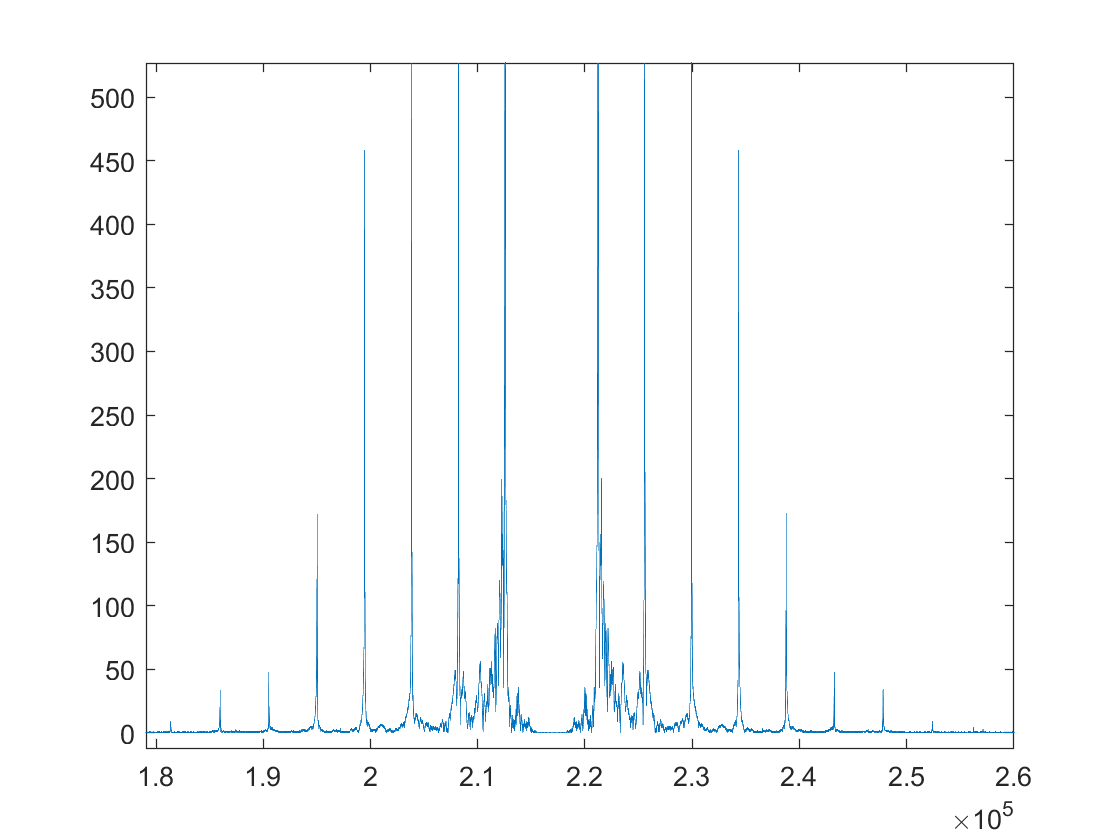

y1_fft = fft(y1);
y1_fft_shift = fftshift(y1_fft);
plot(abs(y1_fft_shift));
xlim([179067 260004])
ylim([-12 527])

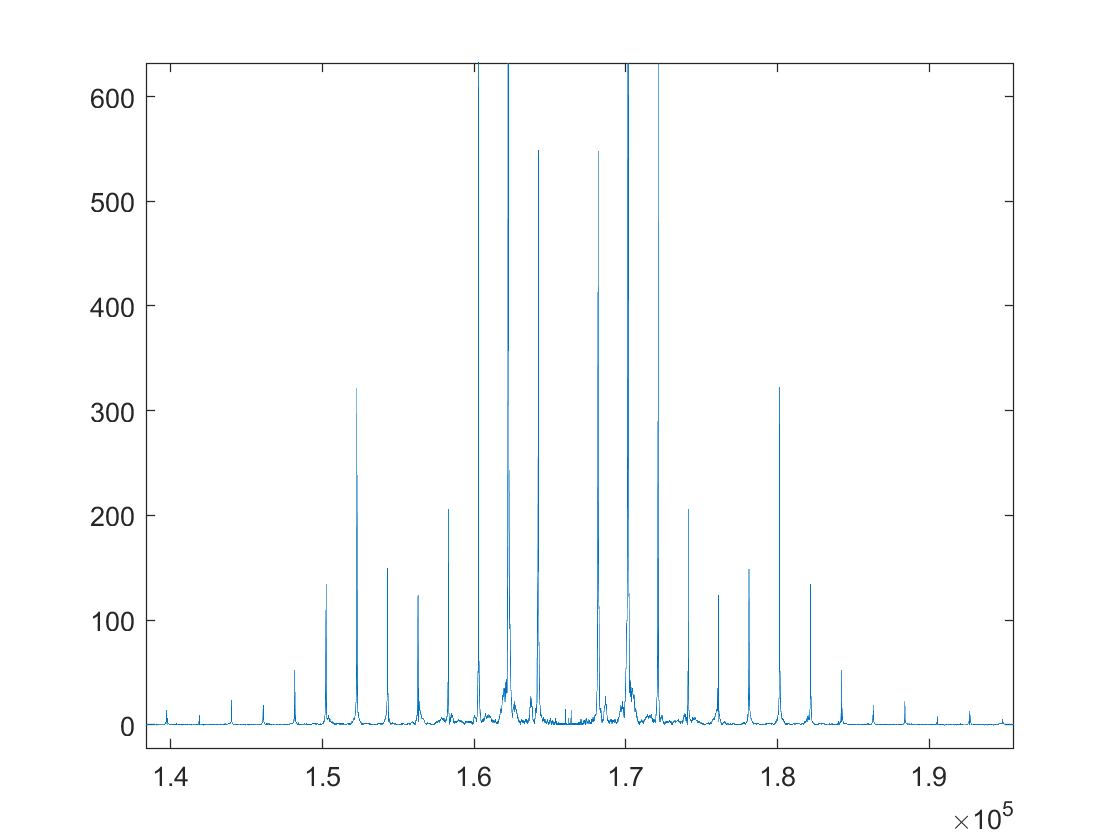

y12_fft = fft(y12);
y12_fft_shift = fftshift(y12_fft);
plot(abs(y12_fft_shift));
xlim([138360 195588])
ylim([-22 632])

sound(y1,Fs1);

sound(y12,Fs12);

## Question : Explain the differences between these two notes